# Stereometry Activity

These sections were lifted from UncalibratedStereoRectificationExample.m .

## 1. Load images and convert to grayscale

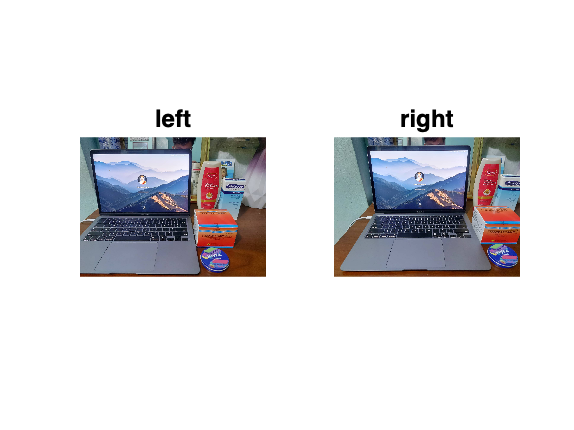

I1 = imread("laptop1.jpg");
I2 = imread("laptop2.jpg");
I1gray = rgb2gray(I1);
I2gray = rgb2gray(I2);
figure;
subplot(1,2,1); imshow(I1); title("left");
subplot(1,2,2); imshow(I2); title("right");

## 2. Find matching points

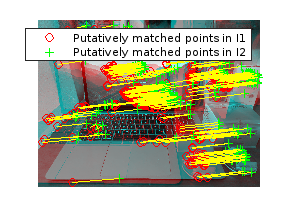

blobs1 = detectSURFFeatures(I1gray, 'MetricThreshold', 2000);
blobs2 = detectSURFFeatures(I2gray, 'MetricThreshold', 2000);

[features1, validBlobs1] = extractFeatures(I1gray, blobs1);
[features2, validBlobs2] = extractFeatures(I2gray, blobs2);

indexPairs = matchFeatures(features1, features2, 'Metric', 'SAD', ...
  'MatchThreshold', 5);

matchedPoints1 = validBlobs1(indexPairs(:,1),:);
matchedPoints2 = validBlobs2(indexPairs(:,2),:);

figure; 
showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2);
legend('Putatively matched points in I1', 'Putatively matched points in I2');

## 3. Estimate Fundamental Matrix 

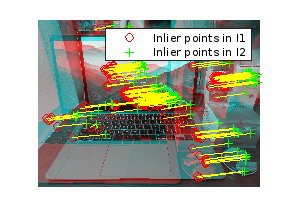

[fMatrix, epipolarInliers, status] = estimateFundamentalMatrix(...
  matchedPoints1, matchedPoints2, 'Method', 'RANSAC', ...
  'NumTrials', 10000, 'DistanceThreshold', 0.1, 'Confidence', 99.99);
  
if status ~= 0 || isEpipoleInImage(fMatrix, size(I1)) ...
  || isEpipoleInImage(fMatrix', size(I2))
  error(['Either not enough matching points were found or '...
         'the epipoles are inside the images. You may need to '...
         'inspect and improve the quality of detected features ',...
         'and/or improve the quality of your images.']);
end

inlierPoints1 = matchedPoints1(epipolarInliers, :);
inlierPoints2 = matchedPoints2(epipolarInliers, :);

figure;
showMatchedFeatures(I1, I2, inlierPoints1, inlierPoints2);
legend('Inlier points in I1', 'Inlier points in I2');

## 4. Rectify images

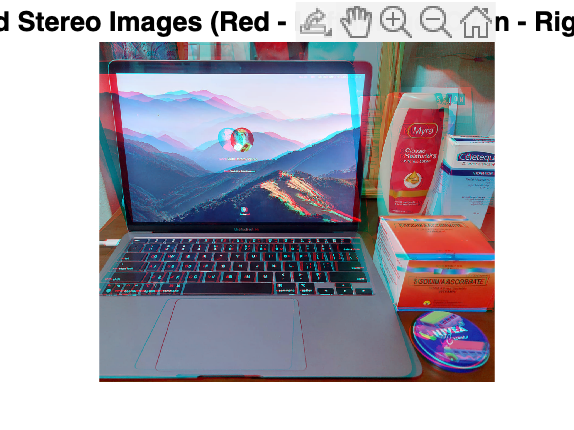

[t1, t2] = estimateUncalibratedRectification(fMatrix, ...
  inlierPoints1.Location, inlierPoints2.Location, size(I2));
tform1 = projective2d(t1);
tform2 = projective2d(t2);
[I1Rect, I2Rect] = rectifyStereoImages(I1, I2, tform1, tform2);
figure;
imshow(stereoAnaglyph(I1Rect, I2Rect));
title('Rectified Stereo Images (Red - Left Image, Cyan - Right Image)');

## 5. Get disparity map

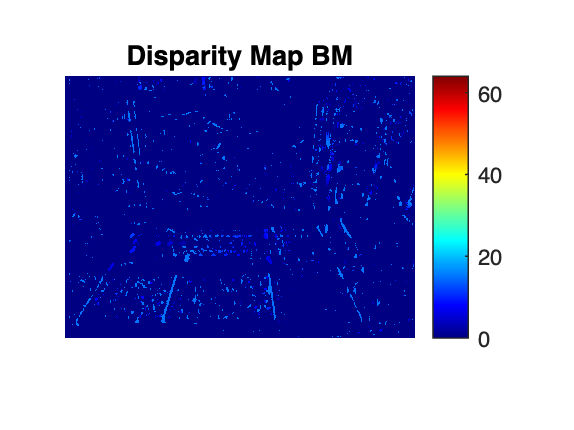

range = [0 16];
disparityMap = disparityBM(I1gray, I2gray);
figure;
imshow(disparityMap, [0, 64]);
title('Disparity Map BM');
colormap jet
colorbar

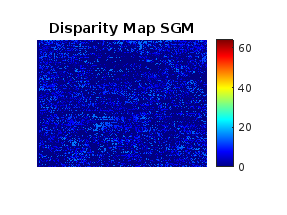

disparityMap = disparitySGM(I1gray, I2gray);
figure;
imshow(disparityMap, [0, 64]);
title('Disparity Map SGM');
colormap jet
colorbar

## 6. Compute depth from disparity map

%Z = b*f./disparityMap % use your b and f
[I1Rect, I2Rect, reprojectionMatrix] = rectifyStereoImages(I1Rect, I2Rect);
